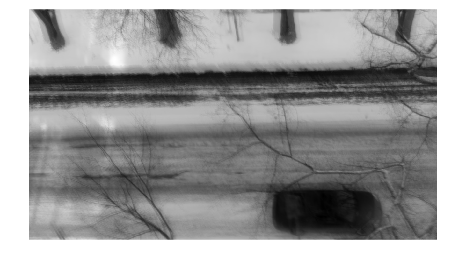

% 1 Mean frame method and foreground extraction, Q1 is done in this section

v1 = VideoReader("streetGray.mp4"); % read the video street.mp4
N_frames = v1.NumFrames; % gets the number of frames of the video
W = v1.Width;
H = v1.height;

sum_frame = zeros(720,1280); % generate array of certain dimension filled with zero

for i = 1:240
    read_frame = read(v1,i); % reads the ith frame
    read_frame = read_frame(:,:,1); % coverrts into grayscale from RGB
    read_frame = cast(read_frame,"double"); % converts the pixel values from integer to float
    read_frame = (read_frame - min(read_frame,[],"all"))/(max(read_frame,[],"all")-min(read_frame,[],"all")); % Normalizing the read_frame 
    sum_frame = sum_frame + read_frame;
end
mean_frame = sum_frame/N_frames;
mean_frame = (mean_frame - min(mean_frame,[],"all"))/(max(mean_frame,[],"all")-min(mean_frame,[],"all")); % Normalizing the mean_frame for showing
imshow(mean_frame);

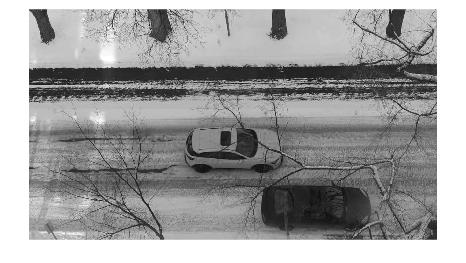

imwrite(mean_frame,"mean_frame.png");

frame_420 = read(v1,420);
frame_420 = frame_420(:,:,1);
frame_420 = cast(frame_420,"double");
frame_420_n = (frame_420 - min(frame_420,[],"all"))/(max(frame_420,[],"all")-min(frame_420,[],"all"));
imshow(frame_420_n);


frame_threshold = abs(frame_420_n - mean_frame)

frame_threshold =     0.5333    0.5859    0.5532    0.5195    0.4760    0.4220    0.3823    0.3707    0.3513    0.3202    0.2770    0.2669    0.2131    0.1750    0.1605    0.1154    0.0851    0.0671    0.0346    0.0312    0.0075    0.0218    0.0045    0.0209    0.0040    0.0134    0.0154    0.0213    0.0038    0.0145    0.0002    0.0422    0.0669    0.0671    0.0518    0.0192    0.0196    0.1082    0.3347    0.2755    0.0010    0.0829    0.0519    0.1005    0.1354    0.1388    0.1585    0.1823    0.2011    0.1768
    0.5038    0.6032    0.5678    0.5531    0.5305    0.4771    0.4184    0.3825    0.3632    0.3268    0.2811    0.2684    0.2364    0.2005    0.1952    0.1482    0.1003    0.0610    0.0323    0.0323    0.0138    0.0081    0.0171    0.0308    0.0010    0.0219    0.0079    0.0094    0.0011    0.0066    0.0045    0.0390    0.0764    0.1008    0.0857    0.0435    0.0063    0.0507    0.2438    0.2761    0.0375    0.0881    0.0726    0.0797    0.1073    0.1136    0.1344    0.1487 

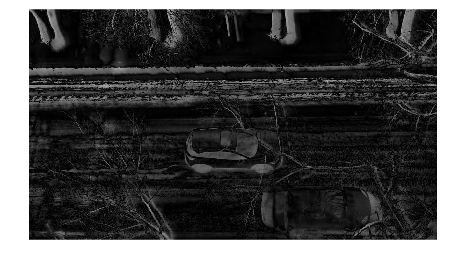

imshow(frame_threshold);

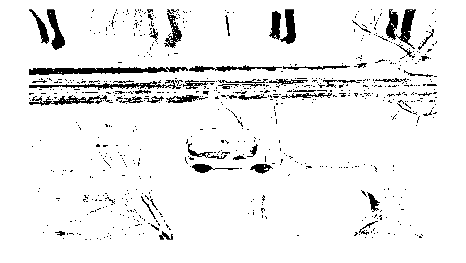

imwrite(frame_threshold,"frame_threshold.png");

% Here in accordinance with the code logic black is the foreground and white is the background
threshold_value = 0.3; % here 0.3 is the optimum value for the foreground extraction

foreground = frame_threshold < threshold_value; % if pixel value > threshold_value white is displayed otherwise black
imshow(foreground);

imwrite(foreground,"foreground_image.png");

% 2 Mixture of Gaussian Method and Q2,Q3,Q4 and Q5 done in this section
 
pixel_str = []; % vector array storing pixel value for all training samples
Y = [];
k = 6;
for j = 1:240    
    read_frame = read(v1,j); % reads the ith frame
    pixel_intermediate = read_frame(360, 640, 1); % gets the specific pixel value for each 1D frame
    pixel_str = [pixel_str pixel_intermediate];
    pixel_str = cast(pixel_str,"double");
end
Y = (pixel_str)';
iter = 700; % number of iterations for ensuring convergence
MOGmodel = fitgmdist(Y,k,'RegularizationValue', 0.1,'Start','randSample','Options',statset('Display','off','MaxIter',iter,'TolFun',1e-6))

MOGmodel = 

Gaussian mixture distribution with 6 components in 1 dimensions
Component 1:
Mixing proportion: 0.131873
Mean:  111.9858

Component 2:
Mixing proportion: 0.272593
Mean:  152.0855

Component 3:
Mixing proportion: 0.250937
Mean:  156.3075

Component 4:
Mixing proportion: 0.250937
Mean:  156.3075

Component 5:
Mixing proportion: 0.068576
Mean:  137.5644

Component 6:
Mixing proportion: 0.025085
Mean:  128.8424





% The above line of code fits the MOG model with k components of our data 

if MOGmodel.Converged == 1
    disp("EM Alogrithm converged")
else
    disp("EM Algorithm did not converged")
end

EM Alogrithm converged



pixel_420 = frame_420(360,640) % taking the specified pixel(360,640) of the 420th frame 

pixel_420 = 141


interval = (pixel_420-0.5):0.0001:(pixel_420+0.5); % interval of size 1 around pixel_420 with step size 0.0001
PDF_420 = pdf(MOGmodel,interval'); % finds the pdf based on MOG model
probability = trapz(interval,PDF_420) % Calculate probability by integrating on the pdf

probability = 0.0061


K = [1 3 6]; % K values given in the lab manual
probability_Q4 = [];

for i = 1:length(K)
    MOGmodel_Q4 = fitgmdist(Y,K(i),'RegularizationValue', 0.1,'Start','randSample','Options',statset('Display','off','MaxIter',iter,'TolFun',1e-6));
    pixel_420 = frame_420(360,640); % taking the specified pixel(360,640) of the 420th frame 
    interval = (pixel_420 - 0.5):0.0001:(pixel_420 + 0.5);
    PDF_420 = pdf(MOGmodel_Q4,interval');
    probability = trapz(interval,PDF_420);
    probability_Q4 = [probability_Q4 probability]; % gives probabillty for different values of K (1, 3, 6)
end
disp("Probability_Q4 is")

Probability_Q4 is


disp(probability_Q4)

    0.0232    0.0102    0.0063




frame_box = [];
frame_Q5 = [];
probability_Q5 = [];

for k = 1:240
    read_frame = read(v1,k);
    frame_box = read_frame(235:484,490:789,1); % gets the centred box as desired in the lab manual
    frame_Q5 = [frame_Q5 reshape(frame_box,[],1)]; % stores box as column vector for each frame
end

frame_Q5 = cast(((frame_Q5)'),"double");
box_test = frame_420(235:484, 490:789); % centering the test frame 
box_test_vec = reshape(box_test,[],1); 

Image_threshold_1 = [];
Image_threshold_2 = [];
Image_threshold_3 = [];

tic
for j = 1:75000
        MOGmodel_Q5 = fitgmdist(frame_Q5(:,j),6,'RegularizationValue', 0.01,'Start','randSample','Options',statset('Display','off','MaxIter',iter,'TolFun',1e-5));
        pixel_test = box_test_vec(j); % getting the pixel from centered test frame column vector
        interval_Q5 = (pixel_test - 0.5):0.0001:(pixel_test + 0.5);
        PDF_Q5 = pdf(MOGmodel_Q5,interval_Q5');
        probability = trapz(interval_Q5,PDF_Q5);
        
        if probability >= 0.0001  % Background
            Image_threshold_1 = [Image_threshold_1 1];
        else % Foreground
            Image_threshold_1 = [Image_threshold_1 0];
        end

        if probability >= 0.001  % Background
            Image_threshold_2 = [Image_threshold_2 1];
        else % Foreground
            Image_threshold_2 = [Image_threshold_2 0];
        end
        
        if probability >= 0.01  % Background
            Image_threshold_3 = [Image_threshold_3 1];
        else % Foreground
            Image_threshold_3 = [Image_threshold_3 0];
        end
end

toc

Elapsed time is 633.766589 seconds.


Image_threshold_1 = reshape(Image_threshold_1,[250, 300]); % reshaping the linear images to orignal centered box size
Image_threshold_2 = reshape(Image_threshold_2,[250, 300]);
Image_threshold_3 = reshape(Image_threshold_3,[250, 300]);

Image_threshold_1 = (Image_threshold_1 - min(Image_threshold_1,[],"all"))/(max(Image_threshold_1,[],"all")-min(Image_threshold_1,[],"all")); % Normalizing the Image
Image_threshold_2 = (Image_threshold_2 - min(Image_threshold_2,[],"all"))/(max(Image_threshold_2,[],"all")-min(Image_threshold_2,[],"all")); % Normalizing the Image 
Image_threshold_3 = (Image_threshold_3 - min(Image_threshold_3,[],"all"))/(max(Image_threshold_3,[],"all")-min(Image_threshold_3,[],"all")); % Normalizing the Image

imwrite(Image_threshold_1,"Q5_threshold_1.png");
imwrite(Image_threshold_2,"Q5_threshold_2.png");
imwrite(Image_threshold_3,"Q5_threshold_3.png");